# 机器人学导论（原书第4版）课后习题

## 第三章

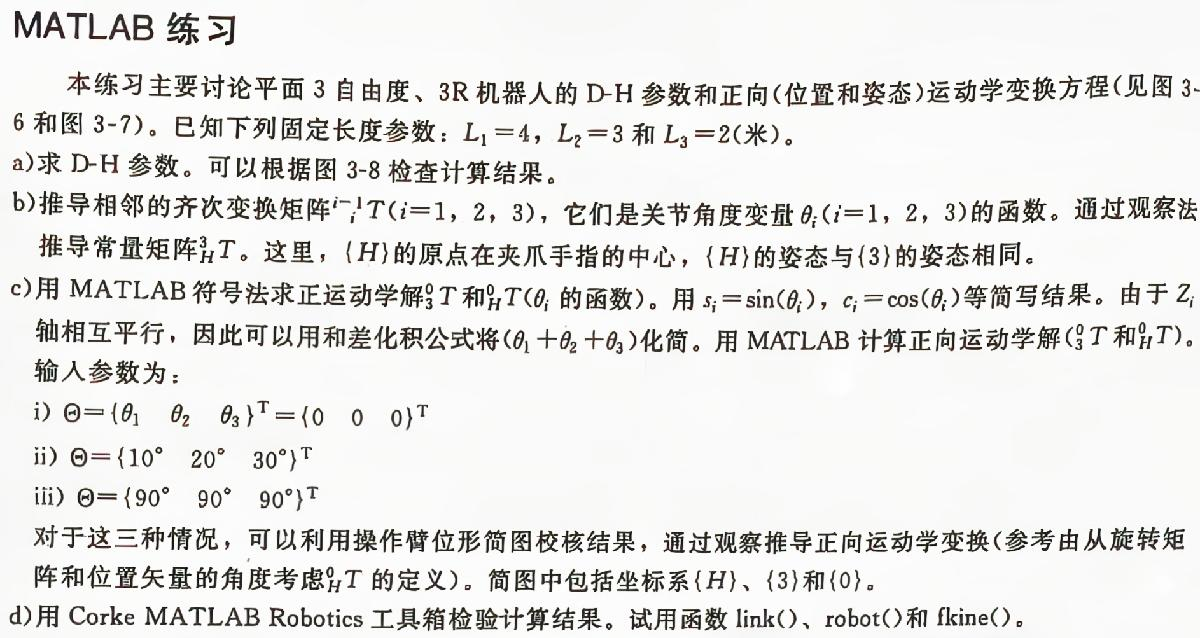

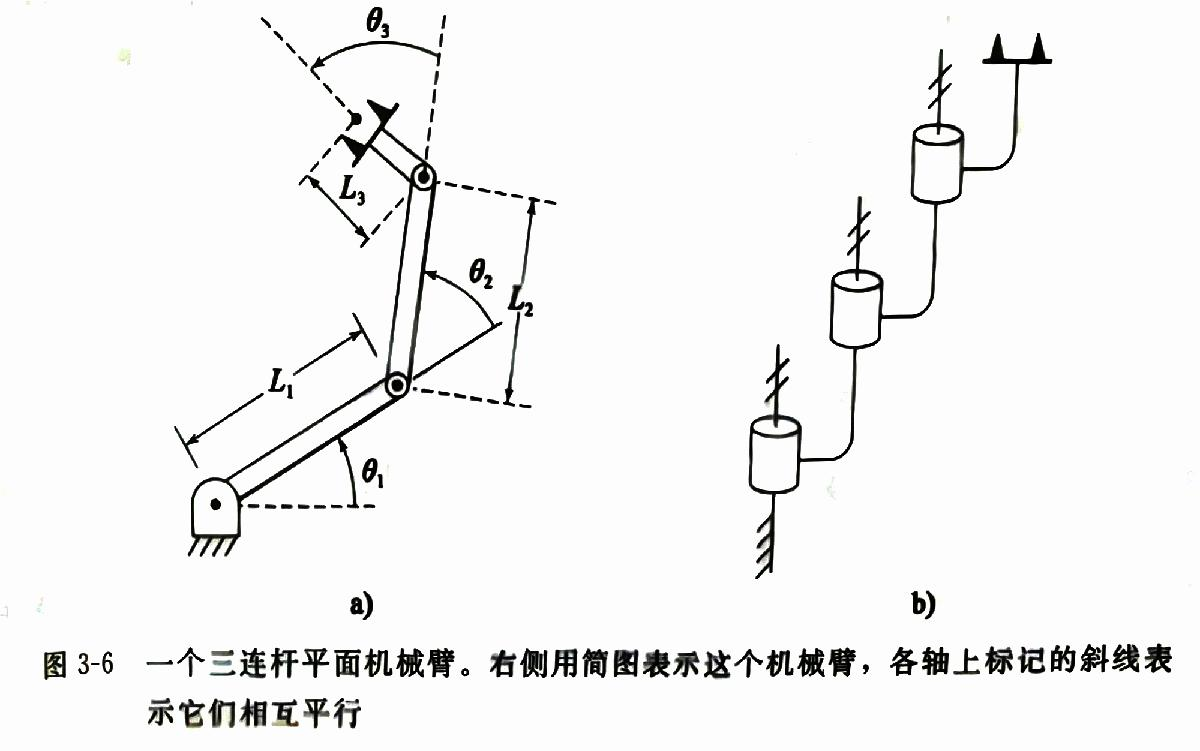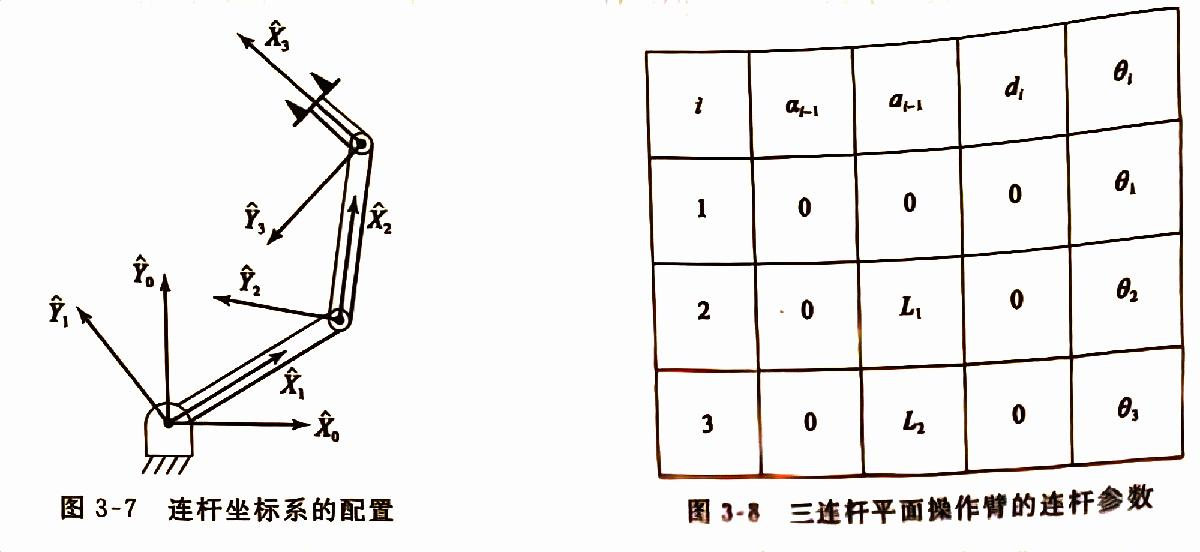

a)

各变量：

clc,clear,close all
syms L1 L2 L3 theta1 theta2 theta3

DH参数：忽略第一行和最后一行

DH=table([0;0;0;0;0], ...
    [0;0;L1;L2;L3], ...
    [0;0;0;0;0], ...
    [0;theta1;theta2;theta3;0], ...
    VariableNames=["alpah_im1","a_im1","d_i","theta_i"],RowNames=["0","1","2","3","H"])

DH = 5×4 table
         alpah_im1    a_im1    d_i    theta_i
         _________    _____    ___    _______

    0        0         0        0     0      
    1        0         0        0     theta1 
    2        0         L1       0     theta2 
    3        0         L2       0     theta3 
    H        0         L3       0     0      


b)

T={zeros(4),zeros(4),zeros(4),zeros(4)};
for i=1:4
    T{i}=link_tf(DH.alpah_im1(i+1),DH.a_im1(i+1),DH.d_i(i+1),DH.theta_i(i+1));
end
% 把长度代入
T01=subs(T{1},[L1 L2 L3],[4 3 2])

$$T01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12=subs(T{2},[L1 L2 L3],[4 3 2])

$$T12 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & 4\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23=subs(T{3},[L1 L2 L3],[4 3 2])

$$T23 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & 3\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T3H=subs(T{4},[L1 L2 L3],[4 3 2])

$$T3H = \left(\begin{array}{cccc} 1 & 0 & 0 & 2\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

c) 首先写符号结果：

T03=T01*T12*T23;
simplify(T03)

$$ans = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) & -\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right) & 0 & 3\,\cos\left(\theta_{1}+\theta_{2}\right)+4\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) & 0 & 3\,\sin\left(\theta_{1}+\theta_{2}\right)+4\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T0H=T03*T3H;
simplify(T0H)

$$ans = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & 2\,\sigma_{2}+3\,\cos\left(\theta_{1}+\theta_{2}\right)+4\,\cos\left(\theta_{1}\right)\\ \sigma_{1} & \sigma_{2} & 0 & 2\,\sigma_{1}+3\,\sin\left(\theta_{1}+\theta_{2}\right)+4\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$

接下来把变量代入：

% i
T03_tmp1=subs(T03,[theta1 theta2 theta3],[0 0 0]),T0H_tmp1=subs(T0H,[theta1 theta2 theta3],[0 0 0])

$$T03\_tmp1 = \left(\begin{array}{cccc} 1 & 0 & 0 & 7\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T0H\_tmp1 = \left(\begin{array}{cccc} 1 & 0 & 0 & 9\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% ii
T03_tmp2=subs(T03,[theta1 theta2 theta3],[10 20 30]*pi/180),T0H_tmp2=subs(T0H,[theta1 theta2 theta3],[10 20 30]*pi/180)

$$T03\_tmp2 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & \frac{\sigma_{3}}{2}-\frac{\sigma_{4}}{2}-\sigma_{2} & 0 & 4\,\cos\left(\frac{\pi }{18}\right)+3\,\cos\left(\frac{\pi }{9}\right)\,\cos\left(\frac{\pi }{18}\right)-3\,\sin\left(\frac{\pi }{9}\right)\,\sin\left(\frac{\pi }{18}\right)\\ \sigma_{2}+\frac{\sigma_{4}}{2}-\frac{\sigma_{3}}{2} & \sigma_{1} & 0 & 4\,\sin\left(\frac{\pi }{18}\right)+3\,\cos\left(\frac{\pi }{9}\right)\,\sin\left(\frac{\pi }{18}\right)+3\,\cos\left(\frac{\pi }{18}\right)\,\sin\left(\frac{\pi }{9}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,\left(\sigma_{4}-\sigma_{3}\right)}{2}-\frac{\sigma_{6}}{2}-\frac{\sigma_{5}}{2}\\ \sigma_{2}=\frac{\sqrt{3}\,\left(\sigma_{6}+\sigma_{5}\right)}{2}\\ \sigma_{3}=\sin\left(\frac{\pi }{9}\right)\,\sin\left(\frac{\pi }{18}\right)\\ \sigma_{4}=\cos\left(\frac{\pi }{9}\right)\,\cos\left(\frac{\pi }{18}\right)\\ \sigma_{5}=\cos\left(\frac{\pi }{18}\right)\,\sin\left(\frac{\pi }{9}\right)\\ \sigma_{6}=\cos\left(\frac{\pi }{9}\right)\,\sin\left(\frac{\pi }{18}\right) \end{array}$$

$$T0H\_tmp2 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & \frac{\sigma_{6}}{2}-\frac{\sigma_{7}}{2}-\frac{\sigma_{2}}{2} & 0 & 4\,\cos\left(\frac{\pi }{18}\right)+\sigma_{3}+3\,\cos\left(\frac{\pi }{9}\right)\,\cos\left(\frac{\pi }{18}\right)-\sigma_{5}-\sigma_{4}-3\,\sin\left(\frac{\pi }{9}\right)\,\sin\left(\frac{\pi }{18}\right)\\ \frac{\sigma_{2}}{2}+\frac{\sigma_{7}}{2}-\frac{\sigma_{6}}{2} & \sigma_{1} & 0 & 4\,\sin\left(\frac{\pi }{18}\right)+\sigma_{2}+\sigma_{7}+3\,\cos\left(\frac{\pi }{9}\right)\,\sin\left(\frac{\pi }{18}\right)+3\,\cos\left(\frac{\pi }{18}\right)\,\sin\left(\frac{\pi }{9}\right)-\sigma_{6}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sigma_{3}}{2}-\frac{\sigma_{5}}{2}-\frac{\sigma_{4}}{2}\\ \sigma_{2}=\sqrt{3}\,\left(\sigma_{5}+\sigma_{4}\right)\\ \sigma_{3}=\sqrt{3}\,\left(\sigma_{7}-\sigma_{6}\right)\\ \sigma_{4}=\cos\left(\frac{\pi }{18}\right)\,\sin\left(\frac{\pi }{9}\right)\\ \sigma_{5}=\cos\left(\frac{\pi }{9}\right)\,\sin\left(\frac{\pi }{18}\right)\\ \sigma_{6}=\sin\left(\frac{\pi }{9}\right)\,\sin\left(\frac{\pi }{18}\right)\\ \sigma_{7}=\cos\left(\frac{\pi }{9}\right)\,\cos\left(\frac{\pi }{18}\right) \end{array}$$

% iii
T03_tmp3=subs(T03,[theta1 theta2 theta3],[90 90 90]*pi/180),T0H_tmp3=subs(T0H,[theta1 theta2 theta3],[90 90 90]*pi/180)

$$T03\_tmp3 = \left(\begin{array}{cccc} 0 & 1 & 0 & -3\\ -1 & 0 & 0 & 4\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T0H\_tmp3 = \left(\begin{array}{cccc} 0 & 1 & 0 & -3\\ -1 & 0 & 0 & 2\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

绘制坐标图验证，蓝、绿、红分别代表了1、2、3组变量，黑色坐标为世界坐标。

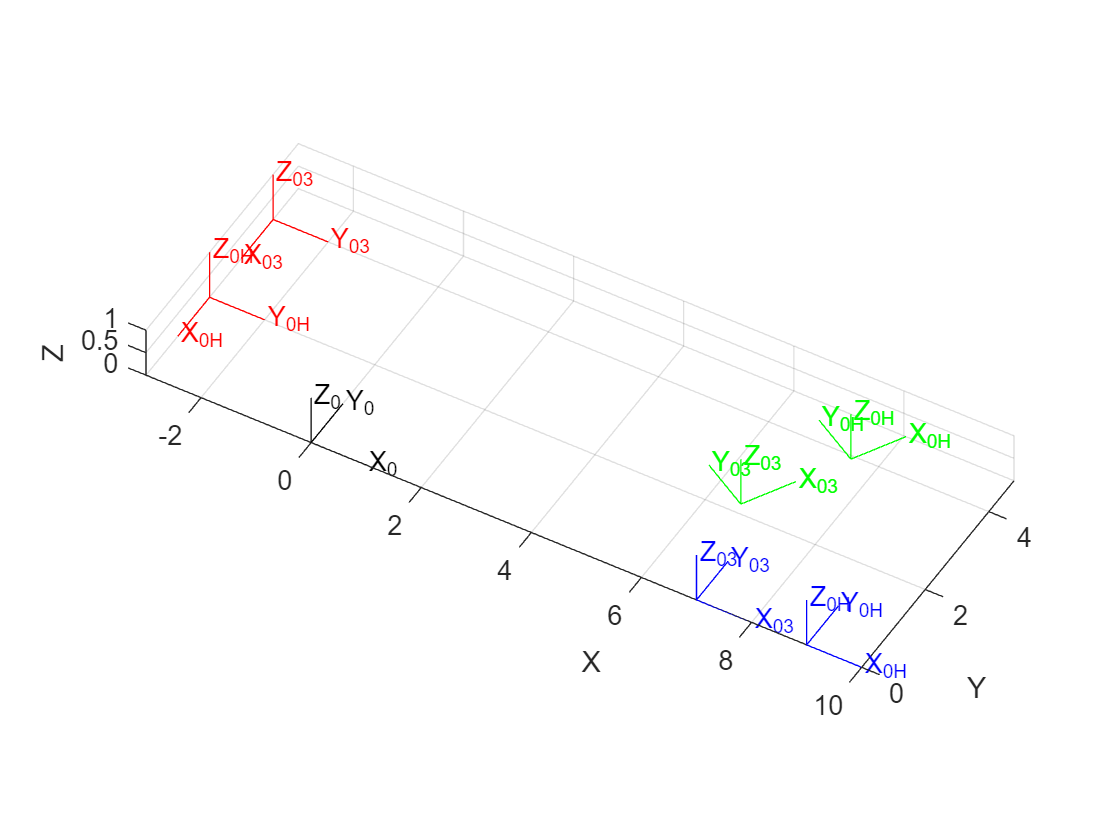

plotvol([-5 10 -5 8 0 1])
view(30,45)
trplot(double(T03_tmp1),'frame','03','color','b'),hold on
trplot(double(T0H_tmp1),'frame','0H','color','b')
trplot(double(T03_tmp2),'frame','03','color','g')
trplot(double(T0H_tmp2),'frame','0H','color','g')
trplot(double(T03_tmp3),'frame','03','color','r')
trplot(double(T0H_tmp3),'frame','0H','color','r')
trplot([1 0 0 0;0 1 0 0;0 0 1 0;0 0 0 1],"frame","0","color",'k')
axis equal
hold off

d) 首先构建一个RRR机器人，最后一个R关节是为了方便展示末端执行器，不属于DH参数，仅供参考

% 仅为方便演示，请忽略最后一个元素
links=[Revolute("a",0) 
    Revolute("a",4)
    Revolute("a",3) 
    Revolute("a",2)];

robot = SerialLink(links, 'name', 'R3bot')

 
robot = 
 
R3bot:: 4 axis, RRRR, stdDH, slowRNE                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|          0|          0|
|  2|         q2|          0|          4|          0|          0|
|  3|         q3|          0|          3|          0|          0|
|  4|         q4|          0|          2|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


可以看到之前计算的结果和用工具箱计算的结果完全相同

T0H1=robot.fkine([0 0 0 0]),T0H_tmp1

 

T0H1 = 
         1         0         0         9
         0         1         0         0
         0         0         1         0
         0         0         0         1


$$T0H\_tmp1 = \left(\begin{array}{cccc} 1 & 0 & 0 & 9\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T0H2=robot.fkine(deg2rad([0 10 20 30])),double(T0H_tmp2)

 

T0H2 = 
    0.5000   -0.8660         0     7.537
    0.8660    0.5000         0     3.927
         0         0         1         0
         0         0         0         1


ans =     0.5000   -0.8660         0    7.5373
    0.8660    0.5000         0    3.9266
         0         0    1.0000         0
         0         0         0    1.0000


T0H3=robot.fkine([0 90 90 90]/180*pi),T0H_tmp3

 

T0H3 = 
         0         1         0        -3
        -1         0         0         2
         0         0         1         0
         0         0         0         1


$$T0H\_tmp3 = \left(\begin{array}{cccc} 0 & 1 & 0 & -3\\ -1 & 0 & 0 & 2\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

可视化仿真，可选择性地uncomment其中一个plot语句查看模拟结果

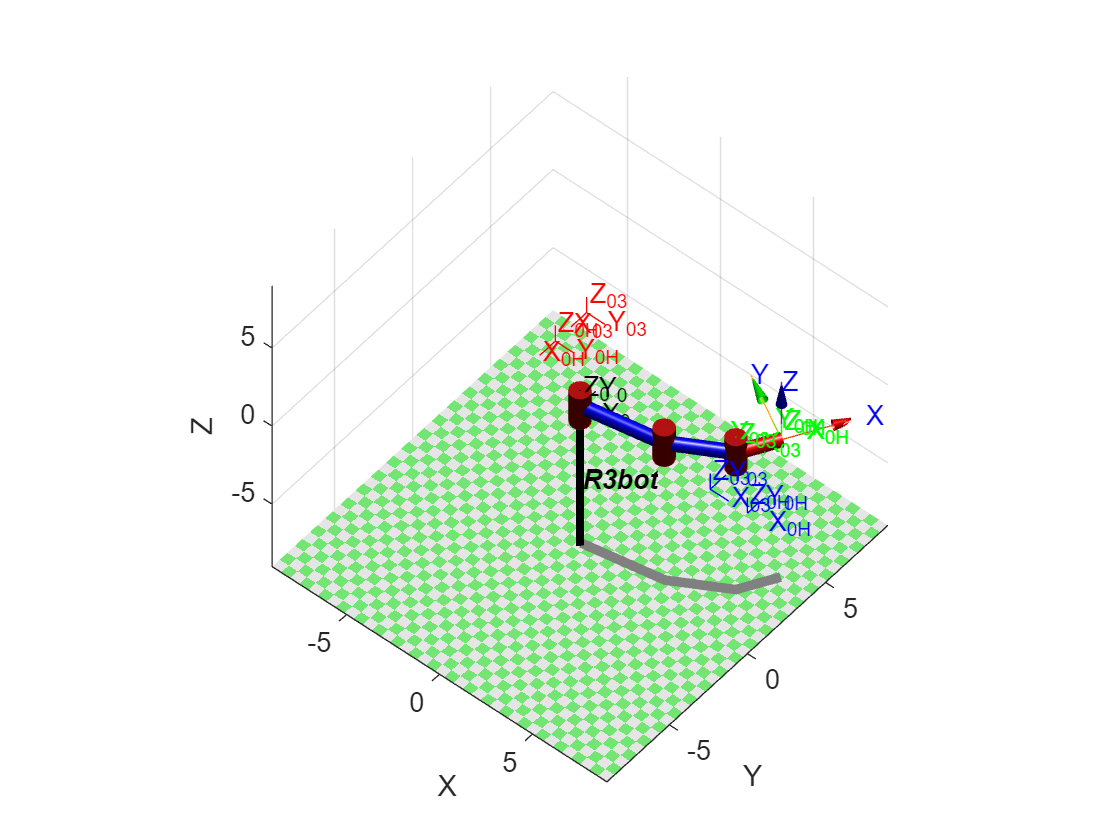

% robot.plot([0 0 0 0])
robot.plot(deg2rad([0 10 20 30]))
% robot.plot([0 90 90 90]/180*pi)
view(40,50)

## 第四章

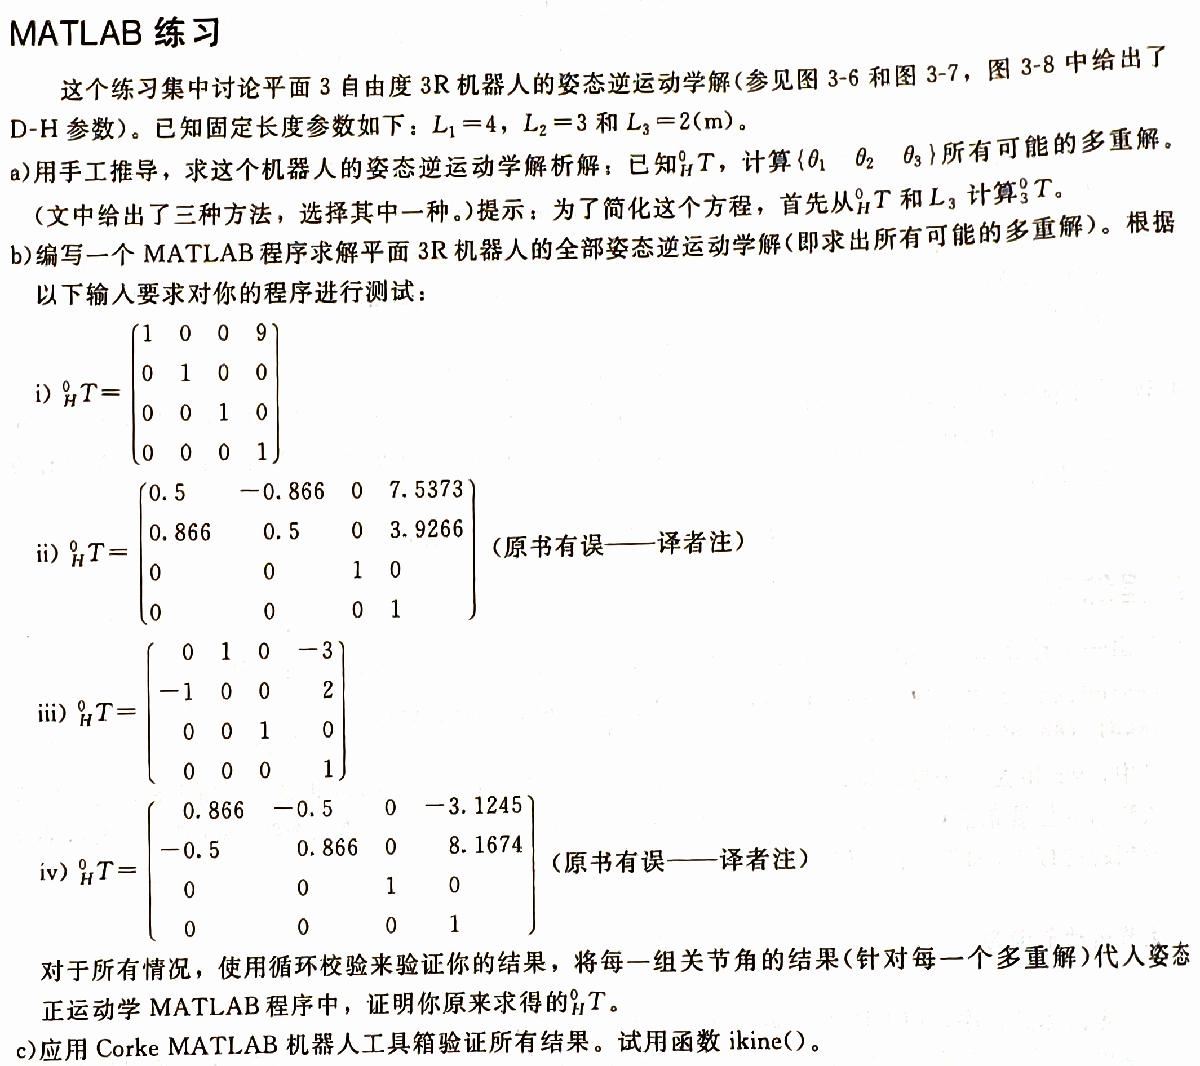

a) 使用几何法，详见末尾自定义函数endeff_ikine

b) 初始化，先构建机器人，接着使用自定义的endeff_ikine函数计算所有可能的逆解。

% 仅为方便演示，请忽略最后一个元素
links=[Revolute("a",0) 
    Revolute("a",4)
    Revolute("a",3) 
    Revolute("a",2)];

robot = SerialLink(links, 'name', 'R3bot')

 
robot = 
 
R3bot:: 4 axis, RRRR, stdDH, slowRNE                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|          0|          0|
|  2|         q2|          0|          4|          0|          0|
|  3|         q3|          0|          3|          0|          0|
|  4|         q4|          0|          2|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


i) 

% 输入的末端执行器坐标矩阵
T0H_1=eye(4);
T0H_1(1,end)=9;
% 求取所有的拟解，可看到这两个拟解是相同的
[t1_1,t2_1,t3_1]=endeff_ikine(T0H_1)

t1_1 =      0
     0


t2_1 =      0
     0


t3_1 =      0
     0


% 验算，可见所求的逆解能够还原出末端执行器的坐标
robot.fkine([[0;0] t1_1 t2_1 t3_1])

 

ans(1) = 
         1         0         0         9
         0         1         0         0
         0         0         1         0
         0         0         0         1

ans(2) = 
         1         0         0         9
         0         1         0         0
         0         0         1         0
         0         0         0         1


可视化，这里可以拖动滑块查看两个逆解对应的不同姿态，对于本小题来说，两个逆解相同，因此姿态也相同

idx=1;

idx = 1

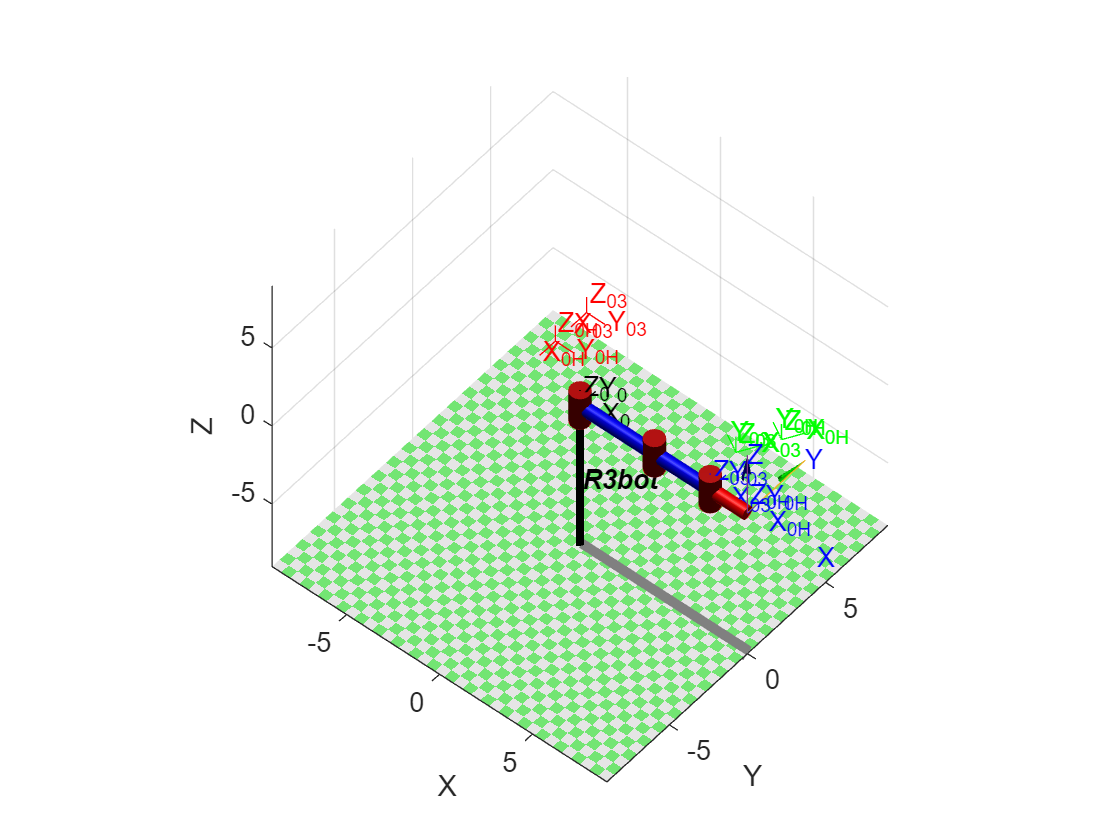

robot.plot([0 t1_1(idx) t2_1(idx) t3_1(idx)])

ii) 

T0H_2=[0.5 -0.866 0 7.5373;
    0.866 0.5 0 3.9266;
    0 0 1 0;
    0 0 0 1];
[t1_2,t2_2,t3_2]=endeff_ikine(T0H_2)

t1_2 =     0.4732
    0.1745


t2_2 =    -0.3491
    0.3491


t3_2 =     0.9230
    0.5236


robot.fkine([[0;0] t1_2 t2_2 t3_2])

 

ans(1) = 
    0.5000   -0.8660         0     7.537
    0.8660    0.5000         0     3.927
         0         0         1         0
         0         0         0         1

ans(2) = 
    0.5000   -0.8660         0     7.537
    0.8660    0.5000         0     3.927
         0         0         1         0
         0         0         0         1


idx=1;

idx = 1

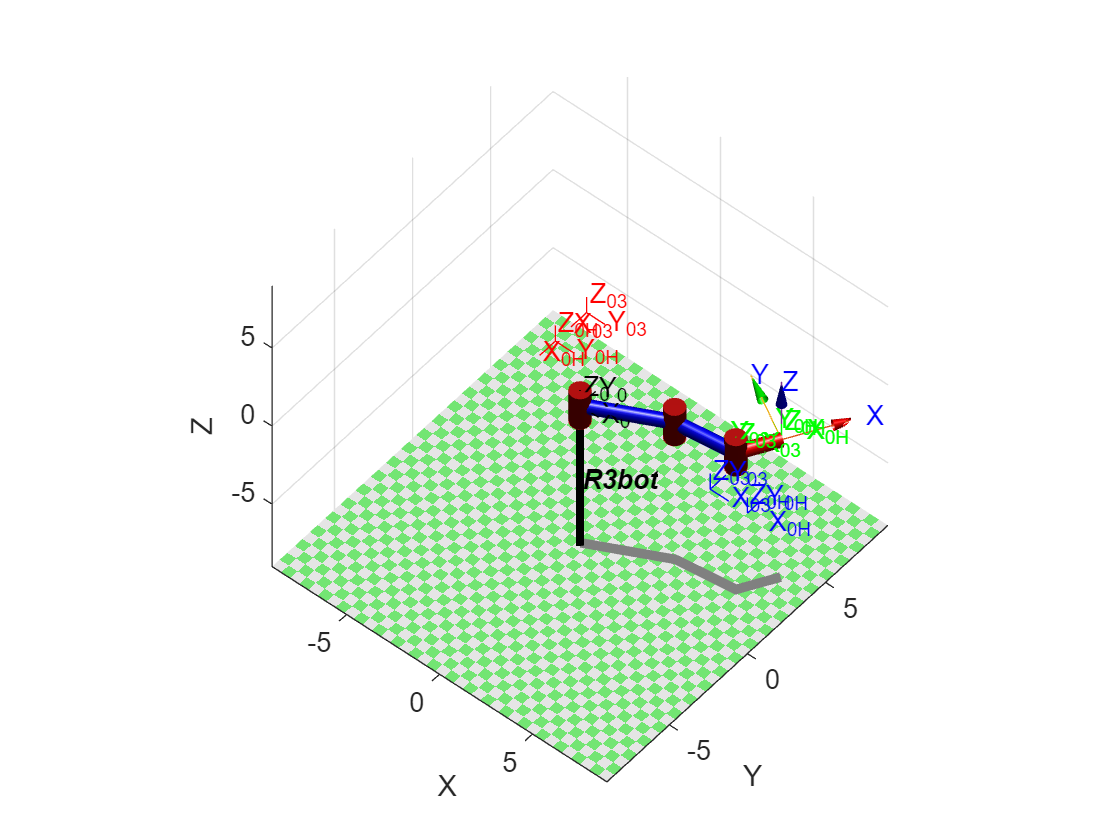

robot.plot([0 t1_2(idx) t2_2(idx) t3_2(idx)])

iii) 

T0H_3=[00 1 0 -3;-1 0 0 2;0 0 1 0;0 0 0 1];
[t1_3,t2_3,t3_3]=endeff_ikine(T0H_3)

t1_3 =     2.8578
    1.5708


t2_3 =    -1.5708
    1.5708


t3_3 =    -2.8578
   -4.7124


robot.fkine([[0;0] t1_3 t2_3 t3_3])

 

ans(1) = 
         0         1         0        -3
        -1         0         0         2
         0         0         1         0
         0         0         0         1

ans(2) = 
         0         1         0        -3
        -1         0         0         2
         0         0         1         0
         0         0         0         1


idx=2;

idx = 2

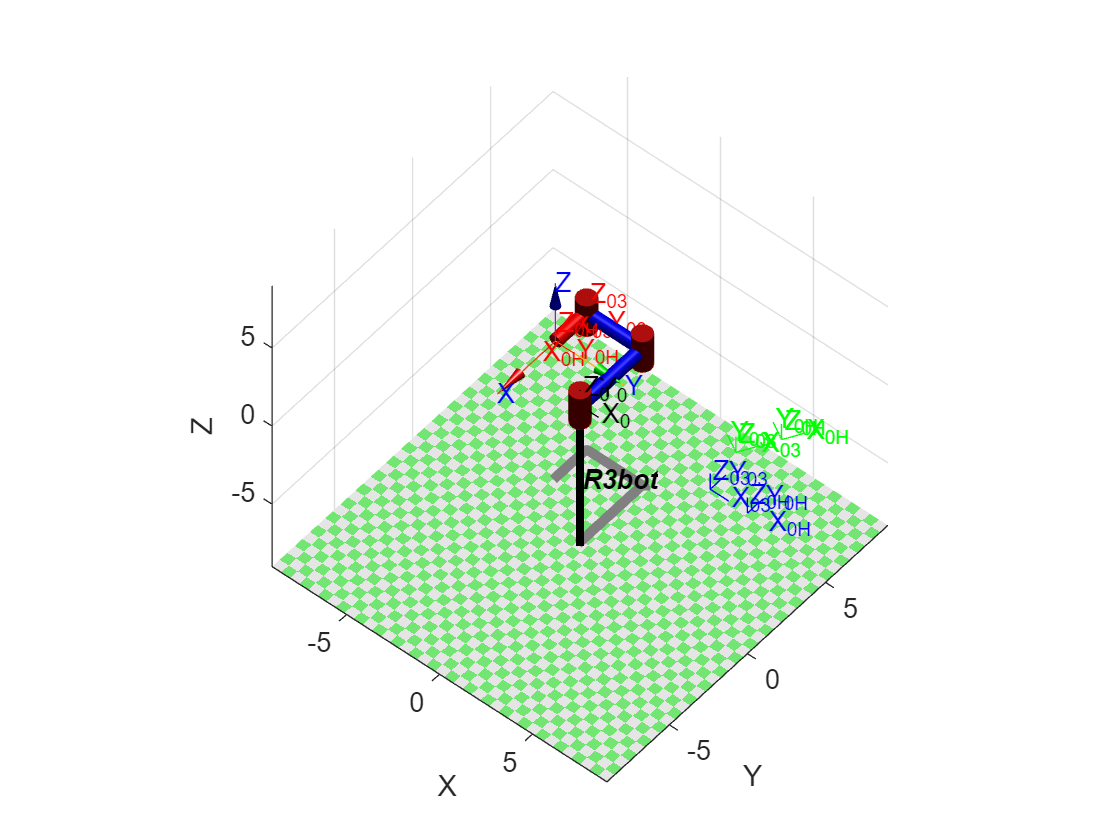

robot.plot([0 t1_3(idx) t2_3(idx) t3_3(idx)])

## 第七章

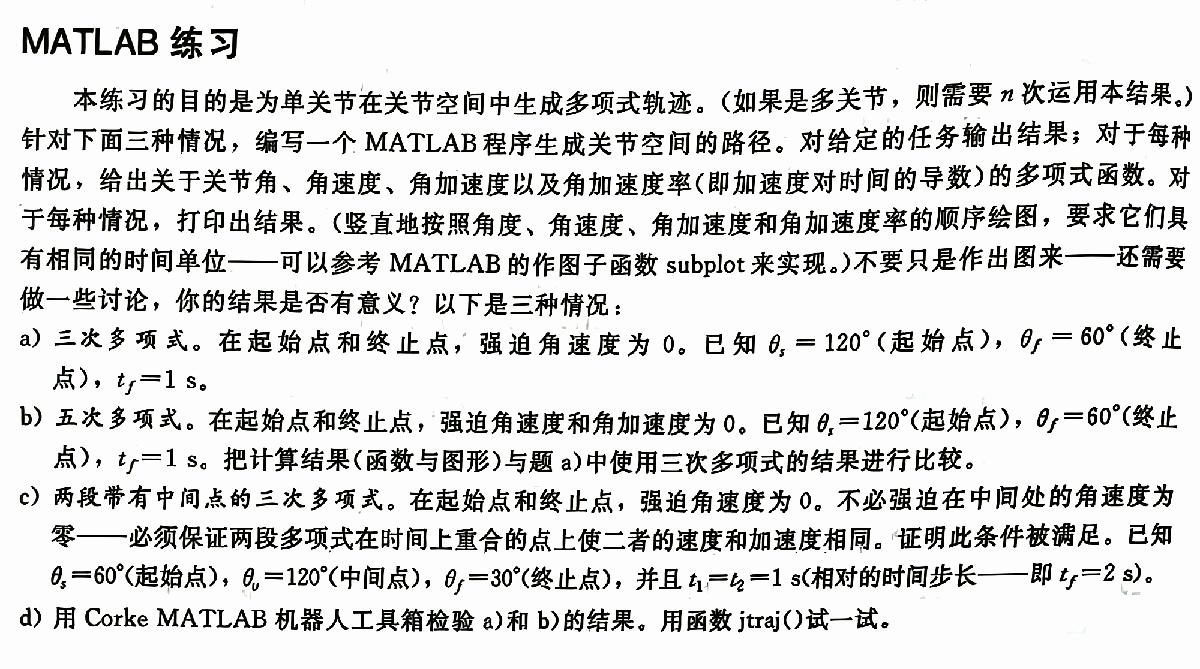

值得注意的是旧版书中，c的边界条件太多了，是无解的。

a) 三次插值，松弛条件

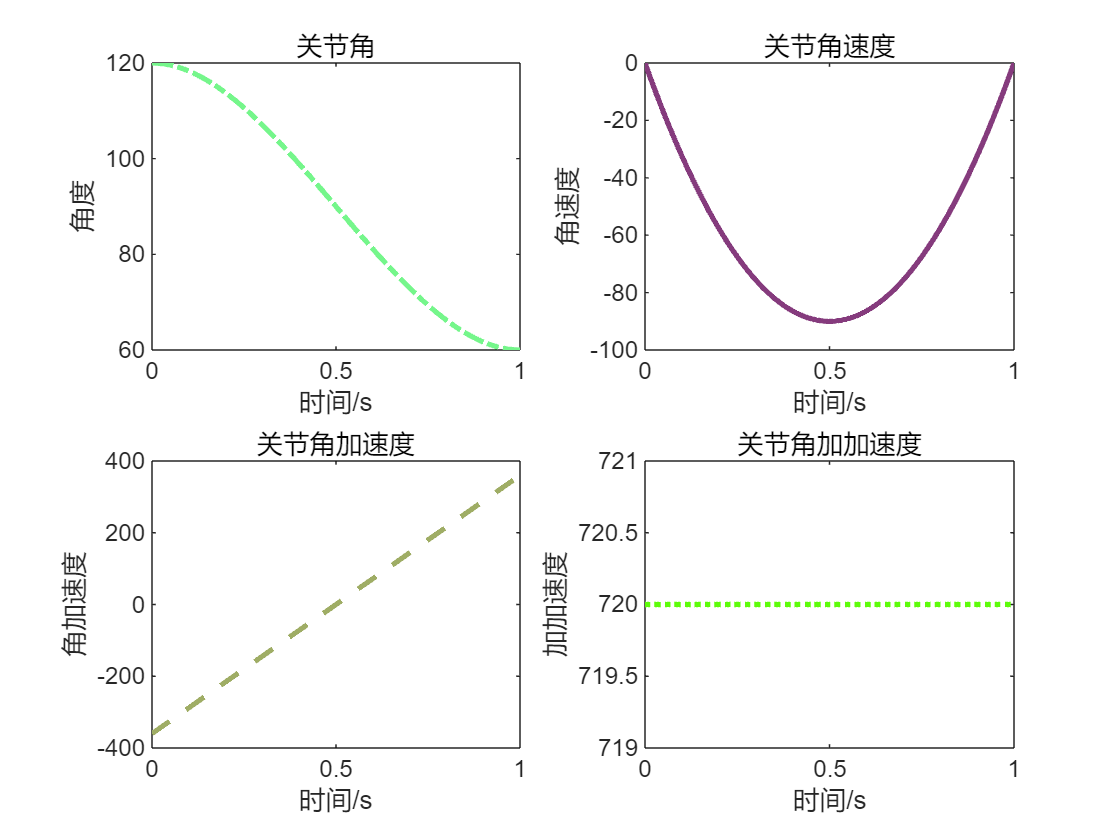

clc,clear
theta0=120;
thetaf=60;
tf=1;
a0=theta0;

a1=0;
a2=3/tf^2*(thetaf-theta0);
a3=-2/tf^3*(thetaf-theta0);

interp_plot([a3 a2 a1 a0],0:1e-3:tf)

b) 五次插值，松弛条件

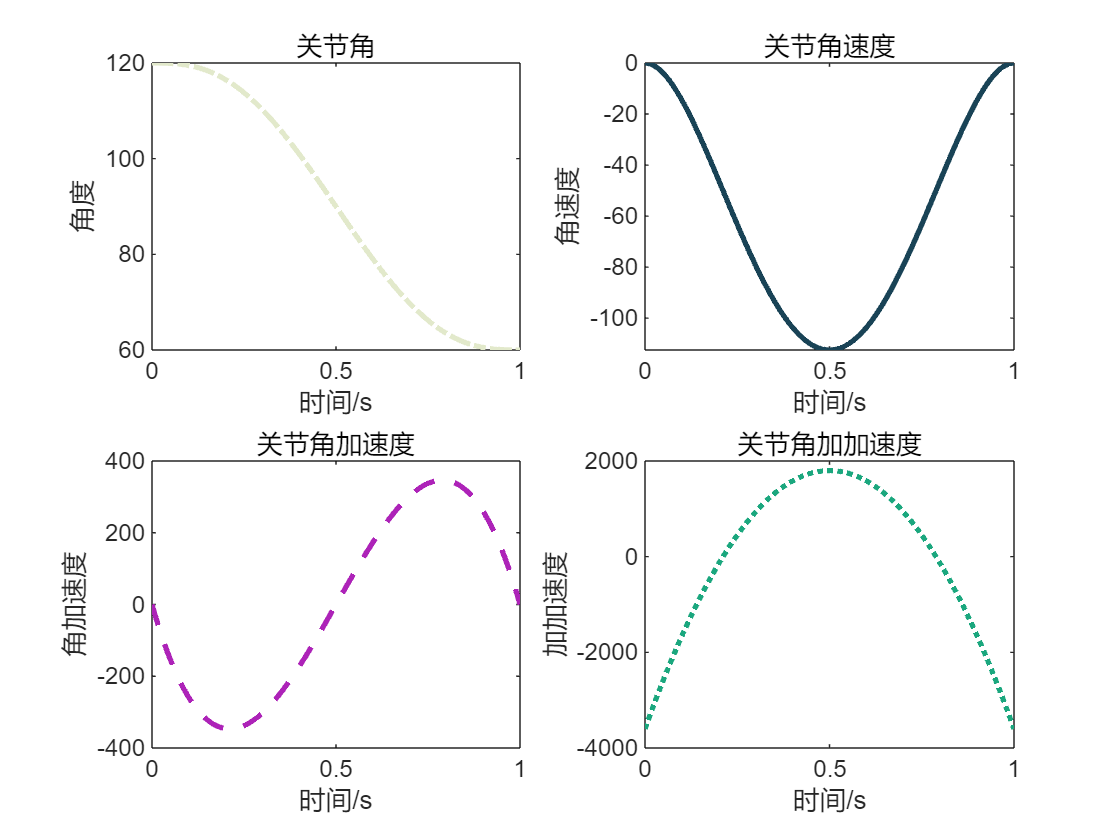

clc,clear
theta0=120;
thetaf=60;
tf=1;
t0p=0;
tfp=0;
t0pp=0;
tfpp=0;

a0=theta0;
a1=t0p;
a2=t0pp/2;
a3=(20*thetaf-20*theta0-(8*tfp+12*t0p)*tf-(3*t0pp-tfpp)*tf^2)/(2*tf^3);
a4=(30*theta0-30*thetaf+(14*tfp+16*t0p)*tf+(3*t0pp-2*tfpp)*tf^2)/(2*tf^4);
a5=(12*thetaf-12*theta0-(6*tfp+6*t0p)*tf-(t0pp-tfpp)*tf^2)/(2*tf^5);

interp_plot([a5 a4 a3 a2 a1 a0],0:1e-3:tf)

c) 稍微复杂一些的三次插值

首先定义所需要的方程

clc,clear
syms t a0 a1 a2 a3 b0 b1 b2 b3 theta thetap thetapp
% 边界
eqs=[theta==a0+a1*t+a2*t^2+a3*t^3;% 角度
    thetap==a1+2*a2*t+3*a3*t^2;% 角速度
    thetapp==2*a2+6*a3*t];% 角加速度
% 内部
eqms=[a1+2*a2*t+3*a3*t^2==b1+2*b2*t+3*b3*t^2;% 角速度
    2*a2+6*a3*t==2*b2+6*b3*t];% 角加速度

将方程中的变量替换为相应的值，可以看到要求解的方程fc

fc=[%始端条件
    subs(eqs(1),[theta thetap thetapp t],[60 0 0 0]);% 角度
    subs(eqs(2),[theta thetap thetapp t],[60 0 0 0]);% 角速度
    % 末端条件
    subs(eqs(1),[theta thetap thetapp t a0 a1 a2 a3],[30 0 0 2 b0 b1 b2 b3]);% 角度
    subs(eqs(2),[theta thetap thetapp t a0 a1 a2 a3],[30 0 0 2 b0 b1 b2 b3]);% 角速度
    % 中间条件
    subs(eqs(1),[theta thetap thetapp t],[120 0 0 1]);% 角度
    subs(eqs(1),[theta thetap thetapp t a0 a1 a2 a3],[120 0 0 1 b0 b1 b2 b3]);% 角度
    subs(eqms(1),t,1);
    subs(eqms(2),t,1)]

$$fc = \left(\begin{array}{c} 60=a_{0}\\ 0=a_{1}\\ 30=b_{0}+2\,b_{1}+4\,b_{2}+8\,b_{3}\\ 0=b_{1}+4\,b_{2}+12\,b_{3}\\ 120=a_{0}+a_{1}+a_{2}+a_{3}\\ 120=b_{0}+b_{1}+b_{2}+b_{3}\\ a_{1}+2\,a_{2}+3\,a_{3}=b_{1}+2\,b_{2}+3\,b_{3}\\ 2\,a_{2}+6\,a_{3}=2\,b_{2}+6\,b_{3} \end{array}\right)$$

求解方程组

solutions=solve(fc,[a0 a1 a2 a3 b0 b1 b2 b3])

solutions = 包含以下字段的 struct :
    a0: 60
    a1: 0
    a2: 405/2
    a3: -285/2
    b0: -240
    b1: 900
    b2: -1395/2
    b3: 315/2


可见所求的多项式系数

a=double([solutions.a3,solutions.a2,solutions.a1,solutions.a0]);
b=double([solutions.b3,solutions.b2,solutions.b1,solutions.b0]);

分段函数需要自己辛苦画图

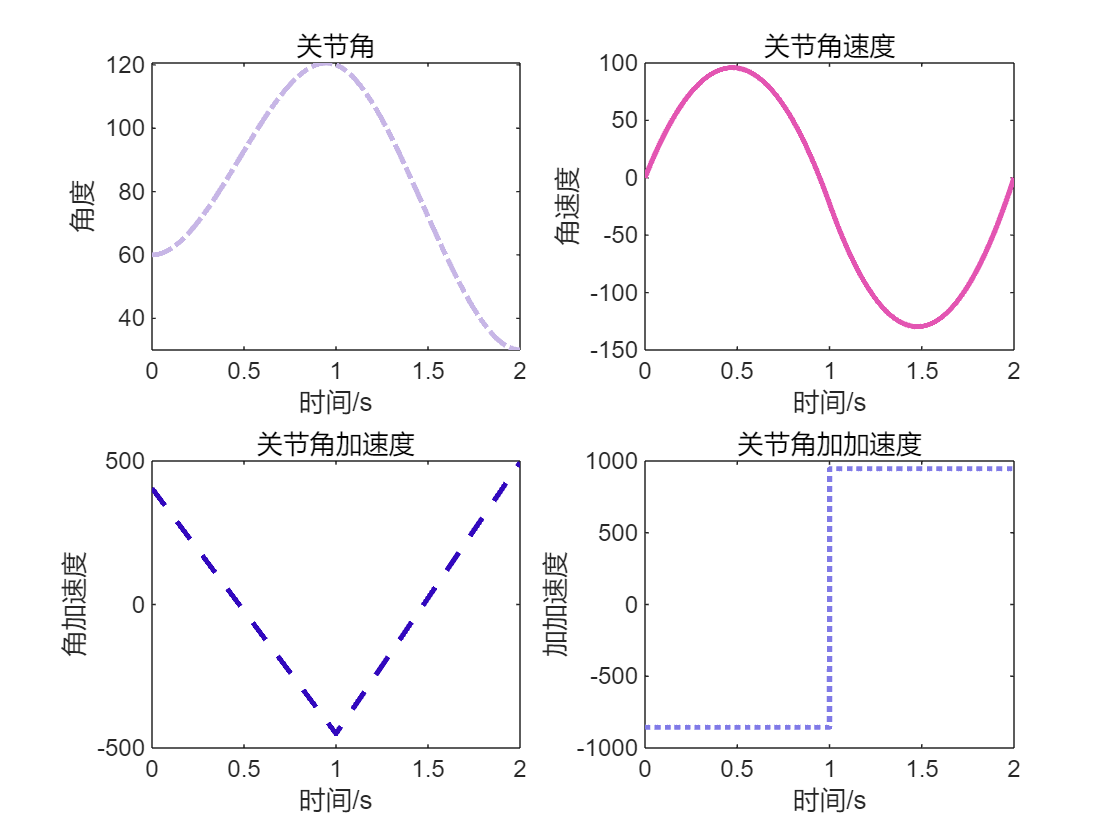

maxn=3;
pta=0:1e-3:1;
ptb=1+1e-3:1e-3:2;
pt=[pta ptb];

% 0阶
ya0=polyval(a,pta);
% 1阶
ya1=polyval(a(1:end-1).*(maxn:-1:1),pta);
% 2阶
ya2=polyval(a(1:end-2).*(maxn:-1:2).*(maxn-1:-1:1),pta);
%3阶
ya3=polyval(a(1:end-3).*(maxn:-1:3).*(maxn-1:-1:2).*(maxn-2:-1:1),pta);
% 0阶
yb0=polyval(b,ptb);
% 1阶
yb1=polyval(b(1:end-1).*(maxn:-1:1),ptb);
% 2阶
yb2=polyval(b(1:end-2).*(maxn:-1:2).*(maxn-1:-1:1),ptb);
%3阶
yb3=polyval(b(1:end-3).*(maxn:-1:3).*(maxn-1:-1:2).*(maxn-2:-1:1),ptb);

% 融合
y0=[ya0 yb0];
y1=[ya1 yb1];
y2=[ya2 yb2];
y3=[ya3 yb3];

subplot(2,2,1)
plot(pt,y0,Color=rand(1,3),LineStyle="-.",LineWidth=2)
title("关节角")
xlabel("时间/s")
ylabel("角度")
subplot(2,2,2)
plot(pt,y1,Color=rand(1,3),LineStyle="-",LineWidth=2)
title("关节角速度")
xlabel("时间/s")
ylabel("角速度")
subplot(2,2,3)
plot(pt,y2,Color=rand(1,3),LineStyle="--",LineWidth=2)
title("关节角加速度")
xlabel("时间/s")
ylabel("角加速度")
subplot(2,2,4)
plot(pt,y3,Color=rand(1,3),LineStyle=":",LineWidth=2)
title("关节角加加速度")
xlabel("时间/s")
ylabel("加加速度")

d) 函数jtraj默认使用五次插值，可见和b中生成的图一样（少了加加速度，因为jtraj没有提供）

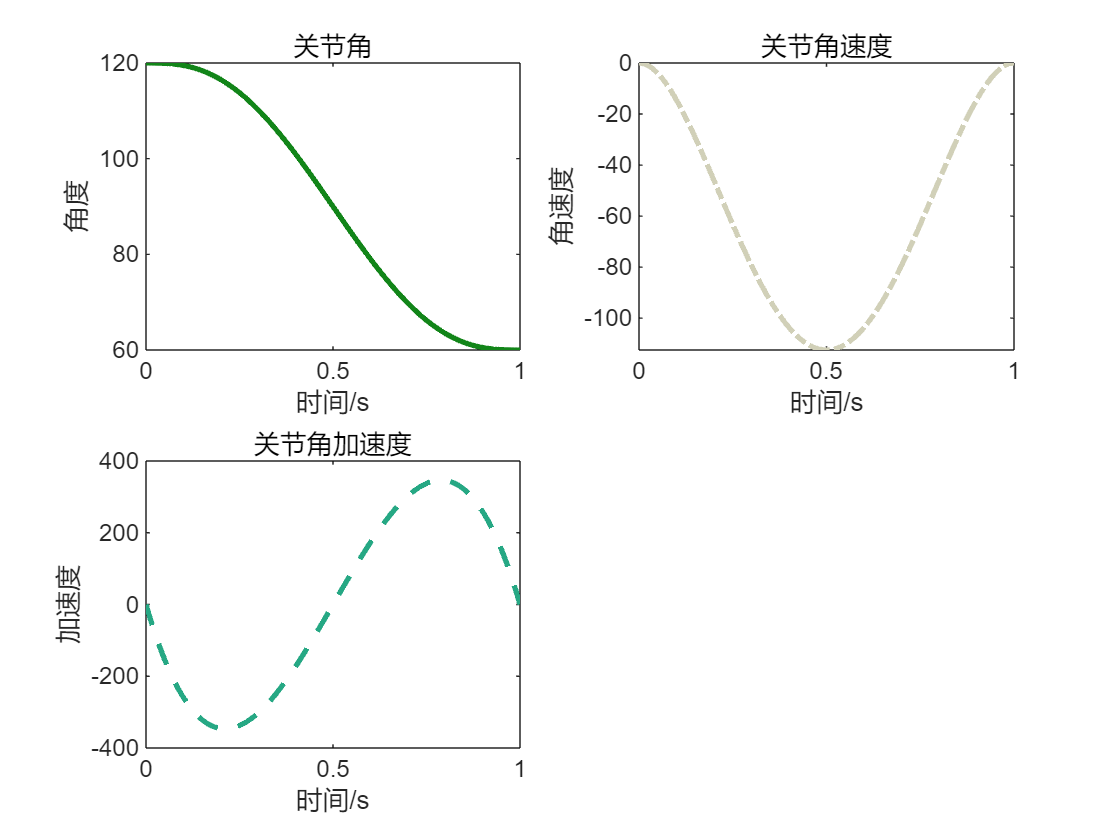

% 随便建一个单自由度旋转机器人
robot=SerialLink(Revolute("a",1));
% trotz(deg2rad(60)),trotz(deg2rad(60)),0:1e-3:1
t=0:1e-3:1;
[q,qd,qdd]=jtraj(120,60,t);
figure
subplot(2,2,1)
plot(t,q,Color=rand(3,1),LineWidth=2,LineStyle="-")
title("关节角")
xlabel("时间/s")
ylabel("角度")
subplot(2,2,2)
plot(t,qd,Color=rand(3,1),LineWidth=2,LineStyle="-.")
title("关节角速度")
xlabel("时间/s")
ylabel("角速度")
subplot(2,2,3)
plot(t,qdd,Color=rand(3,1),LineWidth=2,LineStyle="--")
title("关节角加速度")
xlabel("时间/s")
ylabel("加速度")

## 自定义函数

function T=link_tf(alpha,a,d,theta)
%返回连杆i-1坐标下i的坐标变换矩阵T^(i-1)_i，
% alpha,a,d,theta分别是连杆扭角、连杆长度、连杆偏距和关节角
T=[cos(theta) -sin(theta) 0 a;
    sin(theta)*cos(alpha) cos(theta)*cos(alpha) -sin(alpha) -sin(alpha)*d;
    sin(theta)*sin(alpha) cos(theta)*sin(alpha) cos(alpha) cos(alpha)*d;
    0 0 0 1];
end

function [t1,t2,t3]=endeff_ikine(T_end)
% 通过末端执行器坐标求关节空间坐标，仅适用于本篇所用平面三连杆机器人
% input：机器人末端执行器的坐标
% output：关节坐标的逆解，包含两个可能的解


T3H=eye(4);
T3H(1,end)=2;
T=T_end/T3H;
% 计算相应已知变量
x=T(1,end);
y=T(2,end);
phi=atan2(T(2,1),T(1,1));
l1=4;
l2=3;

% 判断是否可达
if norm([x y])>l1+l2
    error("此空间点不可达！")
end

% 计算theta2,先算正的
theta2=pi-acos((-x^2-y^2+l1^2+l2^2)/(2*l1*l2));
% 计算beta
beta=atan2(y,x);
% 计算psi
psi=acos((x^2+y^2+l1^2-l2^2)/(2*l1*norm([x y])));

if theta2<0
    t2=[theta2;-theta2];
else
    t2=[-theta2;theta2];
end
t1=[beta+psi;beta-psi];
t3=[phi;phi]-(t1+t2);
end

function interp_plot(cef,pt)
% 绘制多项式插值的结果：0~3阶导数
% input：
% cef：插值函数的系数，从最高次到0次排列
% pt：待绘制的点

% 多项式最大次数
maxn=length(cef)-1;

% 0阶
y0=polyval(cef,pt);
% 1阶
y1=polyval(cef(1:end-1).*(maxn:-1:1),pt);
% 2阶
y2=polyval(cef(1:end-2).*(maxn:-1:2).*(maxn-1:-1:1),pt);
%3阶
y3=polyval(cef(1:end-3).*(maxn:-1:3).*(maxn-1:-1:2).*(maxn-2:-1:1),pt);

subplot(2,2,1)
plot(pt,y0,Color=rand(1,3),LineStyle="-.",LineWidth=2)
title("关节角")
xlabel("时间/s")
ylabel("角度")
subplot(2,2,2)
plot(pt,y1,Color=rand(1,3),LineStyle="-",LineWidth=2)
title("关节角速度")
xlabel("时间/s")
ylabel("角速度")
subplot(2,2,3)
plot(pt,y2,Color=rand(1,3),LineStyle="--",LineWidth=2)
title("关节角加速度")
xlabel("时间/s")
ylabel("角加速度")
subplot(2,2,4)
plot(pt,y3,Color=rand(1,3),LineStyle=":",LineWidth=2)
title("关节角加加速度")
xlabel("时间/s")
ylabel("加加速度")
end